## Calculating gyro bias

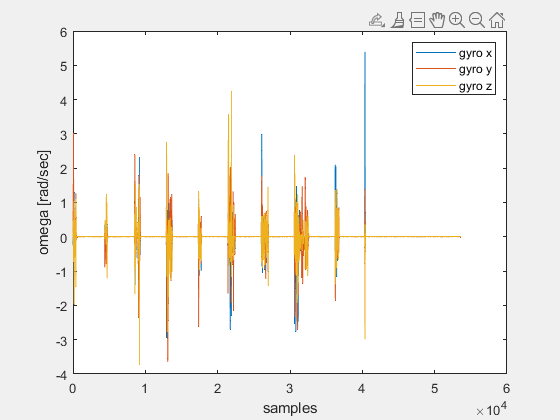

load('rec_2_All_corners_and_120sec_static.mat')
h = figure(1);
set(gcf,'Visible','on')
plot(AngularVelocity.X,'DisplayName','gyro x')
hold on
plot(AngularVelocity.Y,'DisplayName','gyro y')
plot(AngularVelocity.Z,'DisplayName','gyro z')
legend
xlabel('samples')
ylabel('omega [rad/sec]')
[x,~] = ginput(2);

section_for_bias_cancel = [floor(x(1)) floor(x(2))];
bias_gyro_x = mean(AngularVelocity.X(section_for_bias_cancel(1):section_for_bias_cancel(2)));
bias_guro_y = mean(AngularVelocity.Y(section_for_bias_cancel(1):section_for_bias_cancel(2)));
bias_gyro_z = mean(AngularVelocity.Z(section_for_bias_cancel(1):section_for_bias_cancel(2)));

## Processing the dynamic recording

load('rec_3_gyro_dynamic.mat')
h = figure(1);
set(gcf,'Visible','on')
plot(AngularVelocity.X,'DisplayName','gyro x')
hold on
plot(AngularVelocity.Y,'DisplayName','gyro y')
plot(AngularVelocity.Z,'DisplayName','gyro z')
legend
xlabel('samples')
ylabel('omega [rad/sec]')
if 1 % Load limits
    load('section_limits_rec_3_for_gyro_calib.mat')
else % Select new limits
    sections = [];
    counter = 1;
    while 1
        drawnow
        isStopKeyPressed = strcmp('s',get(h,'CurrentCharacter'));
        if isStopKeyPressed
            break
        end
        isSelectKeyPressed = strcmp('g',get(h,'CurrentCharacter'));
        if isSelectKeyPressed
            [x,~] = ginput(2);
            sections(counter,1:2) = [floor(x(1)) floor(x(2))];
            counter = counter + 1;
        end
        pause(5)
    end
end

### Calculate acceleration average value in static parts with known parameters

u_a = zeros(length(sections),3);
load('M.mat', 'M','B')
for section = 1:length(sections)
    avg_acc_x = mean(Acceleration.X(sections(section,1):sections(section,2)));
    avg_acc_y = mean(Acceleration.Y(sections(section,1):sections(section,2)));
    avg_acc_z = mean(Acceleration.Z(sections(section,1):sections(section,2)));
    u_a(section,:) =(M*([avg_acc_x avg_acc_y avg_acc_z]'-B))';
end

### Calculate $u_{g,k}$

q_k_vec = zeros(4,length(sections)-1);
for section = 1:length(sections)-1
    u_a_norm = u_a(section,:)/norm(u_a(section,:));
    section_inds = sections(section,2):sections(section+1,1);
    for ind = 1:length(section_inds)
        if ind == 1
            q_km1 = [0; u_a_norm'];
        else
            q_km1 = q_k_vec(:,section);
        end
        q_k_vec(:,section) = orientation_step(q_km1,[AngularVelocity.X(section_inds(ind)) AngularVelocity.Y(section_inds(ind)) AngularVelocity.Z(section_inds(ind))]);
    end
end

u_gk_vec = zeros(length(sections)-1,3);
for section = 1:length(sections)-1
    u_gk_vec(section,:) = u_g_calc(q_k_vec(:,section),u_a(section,:)');
end

function q_k = orientation_step(q_km1,omega)
    dt = 1/100;
    aux_vec = [-omega(1)*q_km1(2)-omega(2)*q_km1(3)-omega(3)*q_km1(4);...
               omega(1)*q_km1(1)+omega(3)*q_km1(3)-omega(2)*q_km1(4);...
               omega(2)*q_km1(1)-omega(3)*q_km1(2)+omega(1)*q_km1(4);...
               omega(3)*q_km1(1)+omega(2)*q_km1(2)-omega(1)*q_km1(3)];
    q_k = q_km1 + 0.5*aux_vec*dt;
end

function u_gk = u_g_calc(q_k,u_a_km1)
    a = q_k(1);
    b = q_k(2);
    c = q_k(3);
    d = q_k(4);
    R = [a^2+b^2-c^2-d^2 2*(b*c+a*d) 2*(b*d-a*c);...
         2*(b*c-a*d) a^2-b^2+c^2-d^2 2*(c*d+a*b);...
         2*(b*d+a*c) 2*(c*d-a*b) a^2-b^2-c^2+d^2];
    u_gk = R*u_a_km1;
end